if ~isfolder('onion_mask_folder')
    mkdir('onion_mask_folder');
end

if ~isfolder('onion_img_folder')
    mkdir('onion_img_folder');
end

% Get a list of image files and mask files in their respective folders
imageFiles = dir('image/*.jpg');
maskFiles = dir('mask/*.jpg');

% Ensure that the number of image files and mask files are the same
assert(numel(imageFiles) == numel(maskFiles), 'Number of images and masks should be the same.');
numImages = numel(imageFiles)

num_iterations = 10;
n = 40; % erosion radius

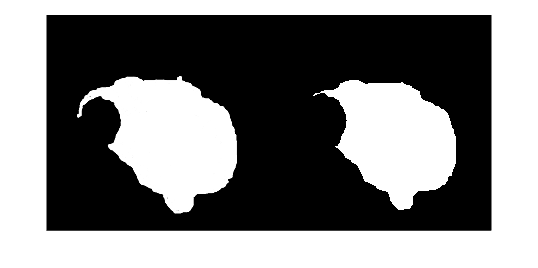

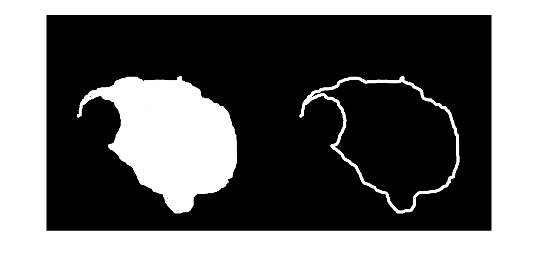

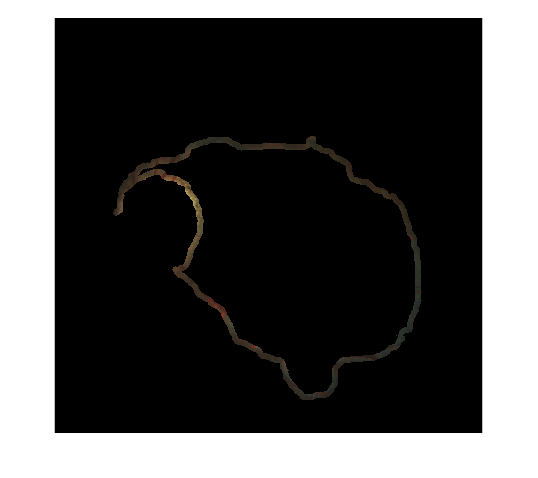

for i = 1:numImages
    % Get the image and mask filenames for the current iteration
    imageFilename = fullfile('image', imageFiles(i).name);
    maskFilename = fullfile('mask', maskFiles(i).name);

    % Create a folder with the same name as the image (e.g., '103')
    [~, imageName, ~] = fileparts(imageFiles(i).name);
    imageoutputFolder = fullfile('onion_img_folder', imageName);
    if ~isfolder(imageoutputFolder)
        mkdir(imageoutputFolder);
    end
    maskoutputFolder = fullfile('onion_mask_folder', imageName);
    if ~isfolder(maskoutputFolder)
        mkdir(maskoutputFolder);
    end

    % Load the image and its corresponding mask
    image = imread(imageFilename);
    mask1 = im2gray(imread(maskFilename));

    mask = mask1;
    for j = 1:num_iterations
        % Perform erosion on the mask
        [mask, mask_diff] = erode(mask, n);

        % Save the mask_diff in the current image's folder
        imwrite(mask_diff, fullfile(maskoutputFolder, sprintf('onion_mask_%d.jpg', j)));

        % Modify the image based on the mask_diff
        new_img = image;
        new_img(repmat(~mask_diff, 1, 1, 3)) = 0;

        % Save the new_img in the current image's folder
        imwrite(new_img, fullfile(imageoutputFolder, sprintf('onion_img_%d.jpg', j)));

        mask = uint8(mask);
    end
end